# Latent variables

A latent variable $z$ measures the expected impact of a set of regressors on each observation $y_i$. Formally, it is the value of a set of regressors for this observation weighted by their corresponding weights, i.e $z_i = \sum_{k \in \text{set}} w_k x_{ki}$. For example, the following model features three sets of regressors: the stimulus regressors (one for each stimulus $s_{ki}$ in each trial stimulus sequence), the history-dependent regressors (one for each lag and possible outcome ) and the session-dependent regressors (as a categorical variable, one regressor per session $S_{ki}$). The three corresponding latent variables are the weighted stimulus evidence, the history-dependent bias (i.e. the tendency to select the rightward response based on previous responses and outcomes) and the session-wise bias. 

T = load_online_dataset();

loading csv file from url...done


M = gum(T, 'resp ~ Stimulus + lag(response|accuracy; Lags=1:10) + cat(session)');


After estimating model weights, the dynamics of the latent variables can be plotted using `plot_latent()`.  

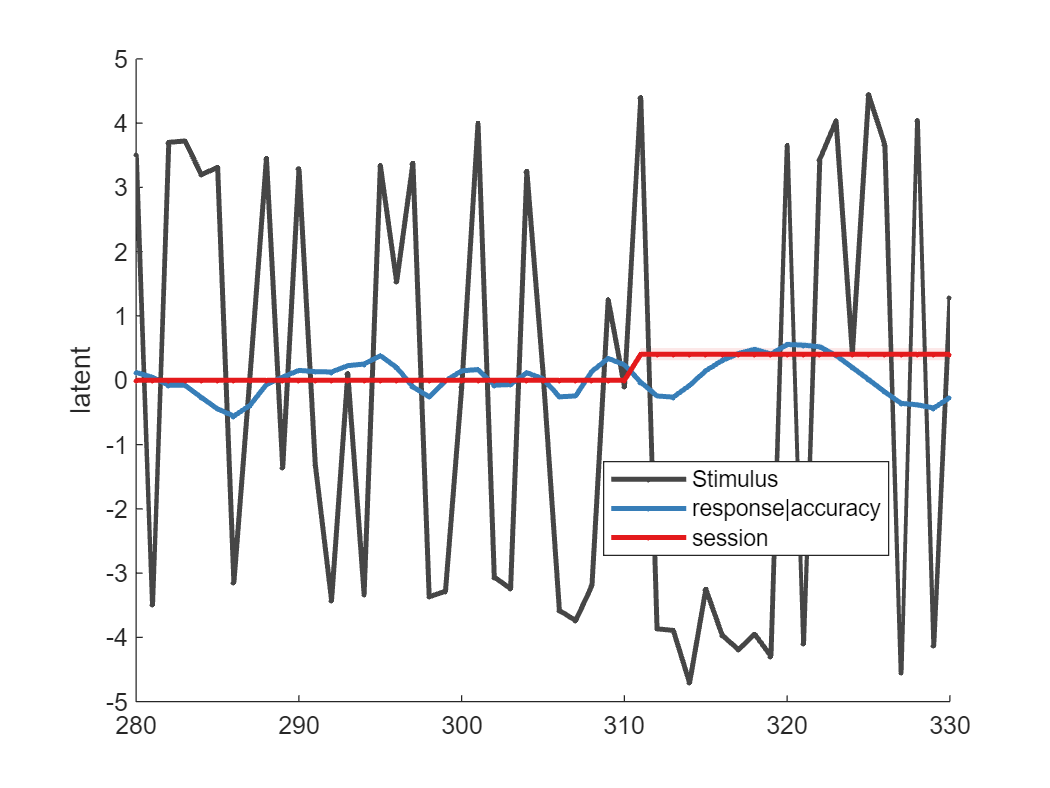

M = M.fit();
figure;
M.plot_latent(280:330);

The larger variance of the weighted stimulus evidence indicates that this set of regressor has a much larger influence on animal behavior (see also explained variance of latent variables below). 

The values can be accessed using `compute_latent(). `This is useful for example if you would like to run subsequent analyses on these latents. For example here we look at the complementary impact of stimulus evidence and history bias on animal choices. As expected, we see that history biases towards the right give rise to slightly more rightward choices than predicted based on stimulus evidence alone, and conversely for history biases towards the left.

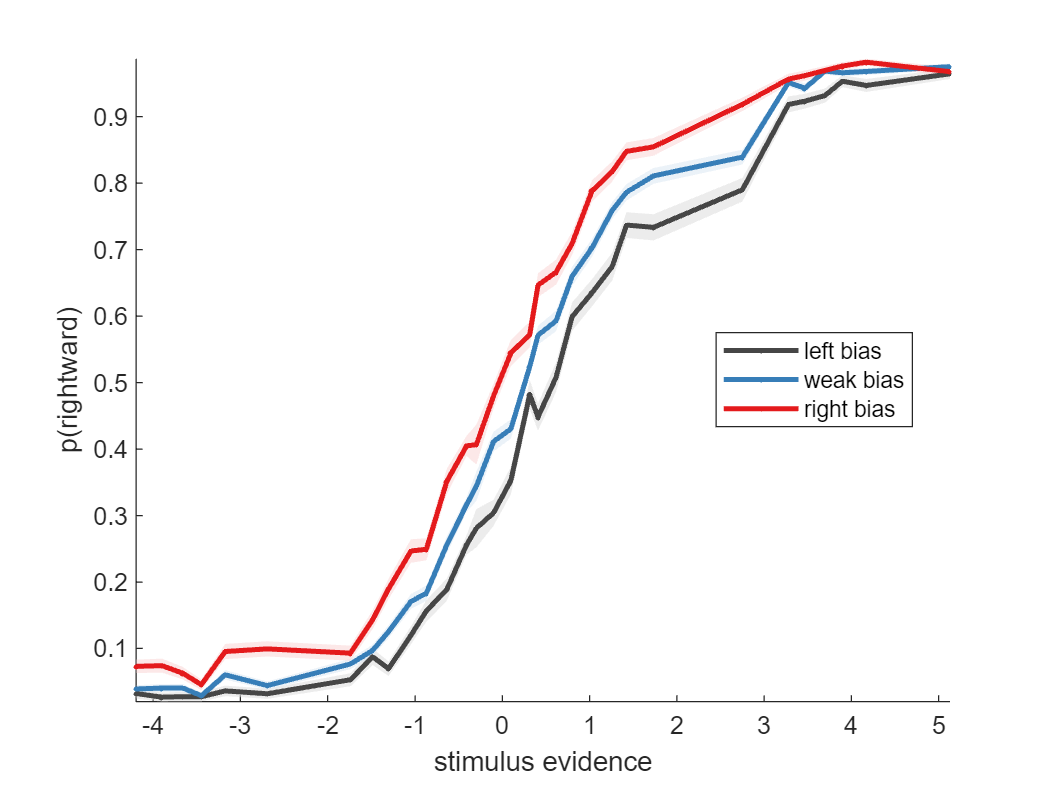

% compute latent variables for model
M = M.compute_latent;

figure; 
stimulus_evidence = M.Predictions.latent(:,1); %weighted stimulus evidence is first latent
history_bias = M.Predictions.latent(:,2); % history bias is second latent
history_bias_bin = discretize(history_bias,[-Inf,-.2,.2,Inf]); % discretize in three values

%plot psychometric curve separately for each history bias bin
h=plot_psychometric_curve_by_history(T.resp,stimulus_evidence,history_bias_bin,30);

#### **Latent explained variance**

`The methods latent_explained_variance`()` and plot_latent_explained_variance() `indicates how much each latent variable contributes to the explained variance. This is computed by looking at the variance explained by each set of regressors alone (with the same weight as in the full model, so in some cases the predictor explained variance can be negative).

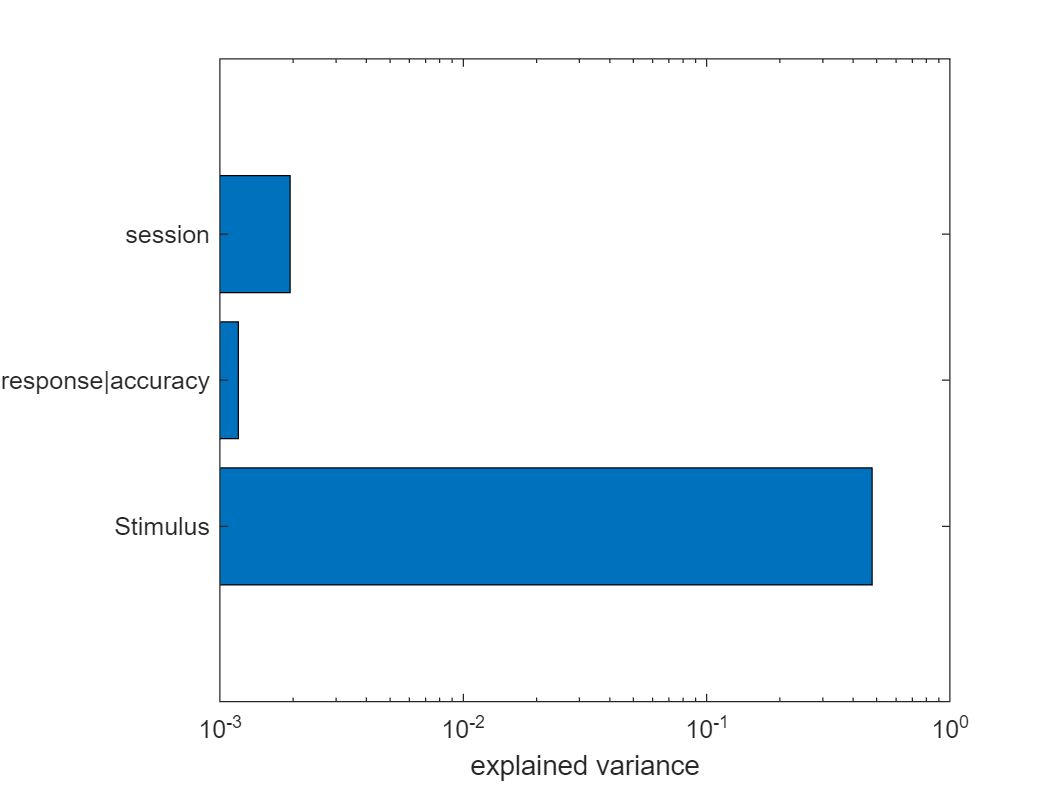

figure;
M.plot_latent_explained_variance();
set(gca, 'xscale','log');

**Next tutorial: **In the [next tutorial](matlab:open('./tutorial9_population_analysis.mlx')) we will see how to run population analysis, when we want to estimate a model in different datasets`.`

function h=plot_psychometric_curve_by_history(y, stim,G,Q)

H = quantile(stim,Q);

H = [-inf unique(H) inf];
nQ = length(H)-2;

nGroup = max(G);

M = zeros(nQ+1,nGroup);
sem = zeros(nQ+1,nGroup);
for g=1:nGroup
    for q=1:nQ+1
        idx = stim>H(q) & stim<=H(q+1); % belongs to quantile
        idx = idx & (G==g); % and belongs to history bias quantile
        nobs = sum(idx);
        M(q,g) = mean(y(idx));
        % standard error for binary data
        sem(q,g) = sqrt( M(q,g)*(1-M(q,g)) / nobs);
    end
end

% values of bins
H = [H(2:end-1) max(stim)];

% plot
lbl = {'left bias','weak bias','right bias'};
h =  wu(H, M, sem,{{},lbl});
axis tight; hold on;

xlabel('stimulus evidence');
ylabel('p(rightward)');
end